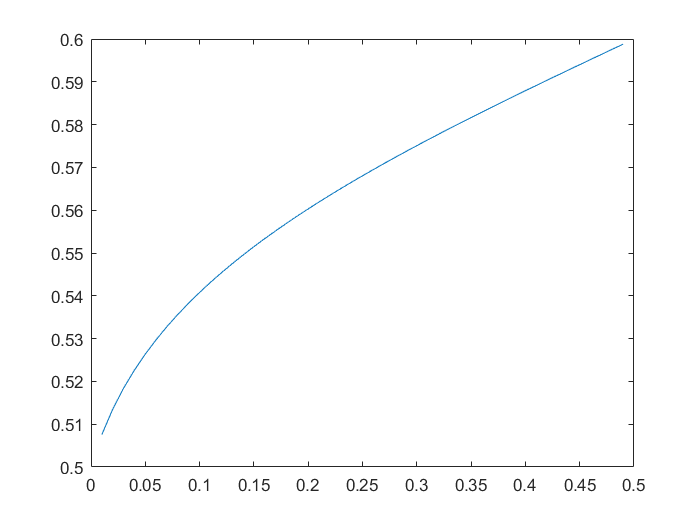

p_real = .5;

center = .6;
spread = .05;
inverse_gamma = @(percentile) double_stunted_gaussian_inverse_gamma(percentile,center,spread);

M = 1;
x = 2; % The "most realistic" x, in my eyes

percentile_values = .01:.01:.49; % Assuming p_real <= center
num_points = length(percentile_values);
E_values = nan(1,num_points);
V_values = nan(1,num_points);

plot(percentile_values,inverse_gamma(percentile_values))

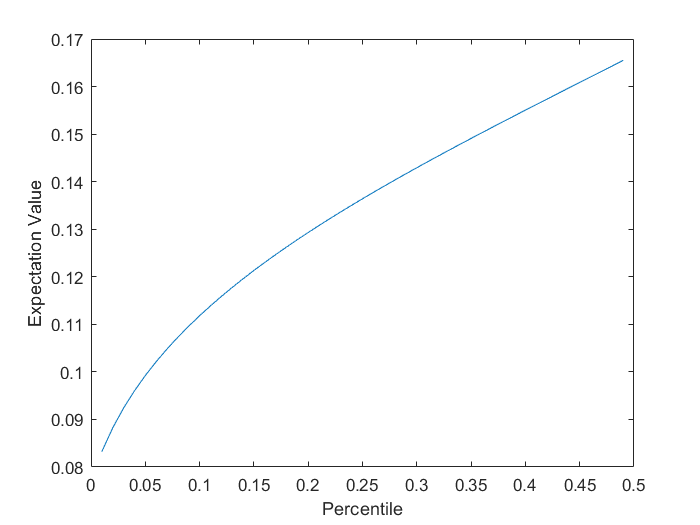


for index = 1:num_points
    % Corresponding to The Knowledgeable User
    p1 = inverse_gamma(percentile_values(index));
    
    % Assuming Inside Out Matching
    p2 = inverse_gamma(1-percentile_values(index));
    
    peer_bet = peer_to_peer(p1,p2,M,x);
    assert(peer_bet.player(1).win_condition == 0,sprintf('index: %d, p1: %d, p2: %d',index,p1,p2)) % Ensure Knowledgeable User is Betting on Underdog
    E_values(index) = (1-p_real)*(peer_bet.pot-peer_bet.player(1).bet_amount) - p_real*peer_bet.player(1).bet_amount;
    V_values(index) = (1-p_real)*(peer_bet.pot-peer_bet.player(1).bet_amount-E_values(index))^2 - p_real*(peer_bet.player(1).bet_amount-E_values(index))^2 ;
end

% Percentile v. Expectation
plot(percentile_values,E_values)
xlabel('Percentile')
ylabel('Expectation Value')

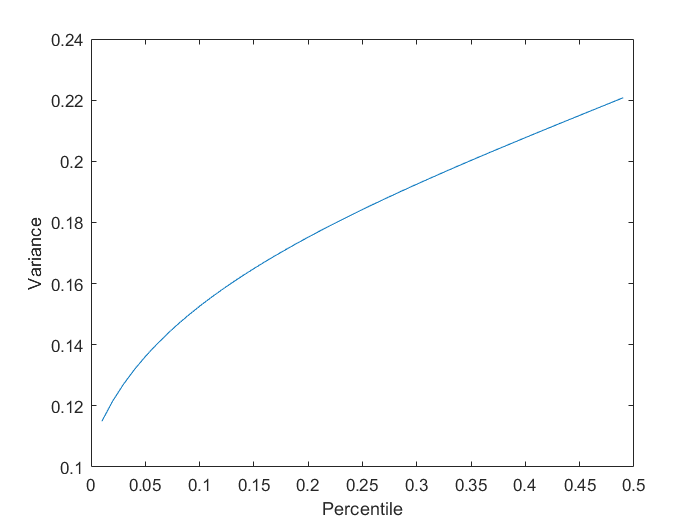


% Percentile v. Variance
plot(percentile_values,V_values)
xlabel('Percentile')
ylabel('Variance')

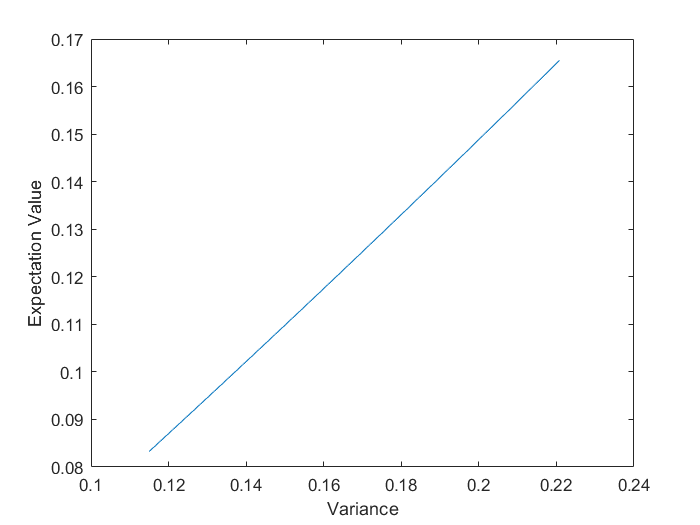


% Variance v. Expectation
plot(V_values,E_values)
xlabel('Variance')
ylabel('Expectation Value')